# Support Vector Machines (SVM) Model: ARMA-Linear

## Setup:

**Configurate the path and clear the workspace, etc.**

clc; close all; clear;
addpath(genpath(fullfile('../')));

## Input model:

***The input features are described as the power levels found at each frequency bin***

***Simply change the directional resolution to run the entire script:***

vec_res = 4;

***Configurations for direction***

index_noise = 1;
% IR Set 
fs = 44100;
IRLen = 40;
dir = "aux_data/IR_Z_fixed/2s/"; % Azimuth
nameIRms = "IR44K_2s_1000ms";
IRms = struct2cell(load(dir+nameIRms));
IRms = IRms{1};
IRms =IRms(:,2);
IRms = [IRms{:}];

% Define 90 degrees resolution (4 categories)
vec90 = [1:6, 36:40; 6:16; 16:26; 26:36];
directions90 = ["Front"; "Left"; "Back"; "Right"];
% Define 36 degrees resolution (8 categories)
vec36 = [1:3, 39:40; 4:8; 9:13; 14:18; 19:23; 24:28; 29:33; 34:38];
directions36 = ["Front"; "Front-Left"; "Left"; "Back-Left"; "Back"; "Back-Right"; "Right"; "Front-Right"];
% Define 18 degrees resolution (20 categories)
vec18 = [1:2, 40; 2:4; 4:6; 6:8; 8:10; 10:12; 12:14; 14:16; 16:18; 18:20; 20:22; ...
    22:24; 24:26; 26:28; 28:30; 30:32; 32:34; 34:36; 36:38; 38:40];
directions18 = string(0:18:351)';
vec9 = (1:40)';
directions9 = string(0:9:351)';
directions_cell = {vec90, directions90; vec36, directions36; vec18, directions18;vec9,directions9};


***Select the number of nfft points: defines the frequency resolution***

nfft = 512;

***Select the directional resolution:***

vec = directions_cell{vec_res,1};
directions = directions_cell{vec_res,2};

***Select order of MUSIC:***

p = 6;


***Run augmentation***

N_bins = 1+ (nfft/2); 
df = fs/(2*((nfft/2)+1));
f = 0:df:(fs-df)/2;

N_noise_samples = 10;
N_augmentations = N_noise_samples*IRLen;

x_train = zeros(N_bins,N_augmentations);
y_train = zeros(N_augmentations,1);
designSpecs = fdesign.lowpass('Fp,Fst,Ap,Ast', 20000, 22050, 0.01, 80, fs);
F = design(designSpecs);
for k = 1:N_noise_samples
    for i = 1:40
        % Augment noise sample
        if index_noise == 1    % White noise
               noise = randn(fs,1);
               noise = filter(F,noise);
            else                   % Pink noise 
                pink = dsp.ColoredNoise('pink',44100,1);    % Normally distributed white noise
                noise = pink();
                noise = noise/max(noise);
        end
        index = ((k-1)*40) + i;
        noise_aug = conv(noise,IRms(:,i));
        noise_aug = noise_aug(1:fs);
       
        [Pxx, ~] = pmusic(noise_aug,p, nfft);
   
        x_train(:,index) = normalize(Pxx, 'range');    % Normalize the Energy levels
        y_train(index) = find(any(i==vec,2),1);
    end
end
y_train = categorical(directions(y_train));

***Train***

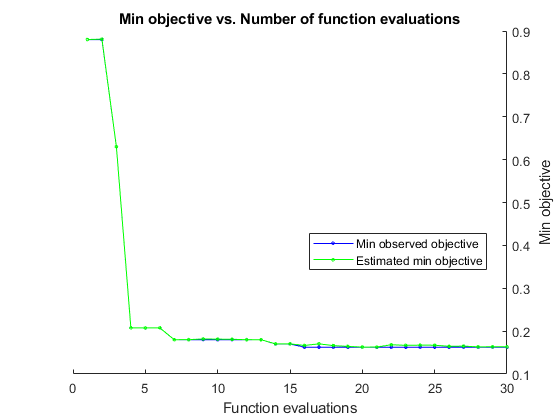

|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Coding | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |        0.88 |      1.3936 |        0.88 |        0.88 |     onevsall |       14.401 |       420.23 |
|    2 | Accept |      0.8975 |      1.4328 |        0.88 |     0.88111 |     onevsall |    0.0011336 |       38.093 |
|    3 | Best   |        0.63 |      4.5069 |        0.63 |     0.63003 |     onevsall |       4.2007 |     0.045364 |
|    4 | Best   |      0.2075 |      22.364 |      0.2075 |     0.20754 |     onevsone |       1.5237 |      0.52991 |
|    5 | Accept |       0.455 |      22.432 |   

% Rename variables for clarity:
%   X: Predictor data (rows are observations)
%   Y: Response data
X = x_train'; 
Y = y_train;

% SVM template with gaussian kernel (RBF)
t = templateSVM('KernelFunction','gaussian');

Mdl = fitcecoc(X,Y,'Coding',"onevsall",'Learners',t, "Prior","uniform", "OptimizeHyperparameters","auto",...
    "HyperparameterOptimizationOptions",struct('AcquisitionFunctionName','expected-improvement-plus'));

## Evaluation

% Compute resubstitution classification error to obtain training error 
train_error = resubLoss(Mdl, 'lossfun', 'classiferror');
disp("Training error: " + train_error*100 + "%");

Training error: 1.25%


% Cross-validate classifier
CVMdl = crossval(Mdl);
% Compute cross-validation classification error: 
cv_error = kfoldLoss(CVMdl, 'lossfun','classiferror');

disp("Validation error: " + cv_error*100 + "%");

Validation error: 16.25%


***Case 1: Low errors***

***    If the validation error is higher than the training error this indicates that there is a case of HIGH VARIANCE***

***    High variance can be solved by adding more training data***

***Case 2: High errors***

***    If both the validation and training error are high this indicates a case of HIGH BIAS***

***    High bias asks for more distinct features***

## Test on same reverberation duration

***Augment test samples***

N_tests = 10;
N_augmentations = N_tests*IRLen;% 100 noise samples * 40 augmentations = 4000 augmented samples

x_test = zeros(N_bins,N_augmentations);
y_test = zeros(N_augmentations,1);

for k = 1:N_noise_samples
    for i = 1:40
        % Augment noise sample
        noise = randn(fs,1);
        noise = filter(F,noise);
        index = ((k-1)*40) + i;
        noise_aug = conv(noise,IRms(:,i));
        noise_aug = noise_aug(1:fs);
       
        [Pxx, ~] = pmusic(noise_aug,p, nfft);
        
        x_test(:,index) = normalize(Pxx, 'range');    % Normalize the Energy levels
        y_test(index) = find(any(i==vec,2),1);
    end
end
y_test = categorical(directions(y_test));

***Predict test samples***

y_pred = predict(Mdl,x_test');
y_pred(randsample(numel(y_pred),5))

ans = 5×1 categorical array
     126 
     279 
     153 
     72 
     63 


%numMisclass = sum(~strcmp(,species(idxVal)));
test_error = 1-sum(y_pred==y_test)/N_augmentations;
disp("Test error: " + test_error*100 + "%");

Test error: 13%


## Test on augmented noise with other reverberations

***Load in other IR set***

fs = 44100;
IRLen = 40;
dir = "aux_data/IR_Z_fixed/2s/"; % Azimuth
test_acc = zeros(5,1);
names = ["IR44K_2s_10ms";
"IR44K_2s_50ms";
"IR44K_2s_100ms";
"IR44K_2s_500ms";
"IR44K_2s_1000ms"];
for index_IR = 1:5
    IR_reverb = struct2cell(load(dir+names(index_IR)));
    IR_reverb = IR_reverb{1};
    IR_reverb =IR_reverb(:,2);
    IR_reverb = [IR_reverb{:}];
    
    N_tests = 10;
    N_augmentations = N_tests*IRLen;
    
    x_test_reverb = zeros(N_bins,N_augmentations);
    y_test_reverb = zeros(N_augmentations,1);
    
    for k = 1:N_tests
        for i = 1:40
            % Augment noise sample
            if index_noise == 1    % White noise
               noise = randn(fs,1);
               noise = filter(F,noise);
            else                   % Pink noise 
                pink = dsp.ColoredNoise('pink',44100,1);    % Normally distributed white noise
                noise = pink();
                noise = noise/max(noise);
            end
            index = ((k-1)*40) + i;
            noise_aug = conv(noise,IRms(:,i));
            noise_aug = noise_aug(1:fs);
            
            [Pxx, ~] = pmusic(noise_aug,p, nfft);
            
            x_test_reverb(:,index) = normalize(Pxx, 'range');
            y_test_reverb(index) = find(any(i==vec,2),1);
        end
    end
    
    y_test_reverb = categorical(directions(y_test_reverb));

***Predict test samples***

    y_pred_reverb = predict(Mdl,x_test_reverb');
    y_pred_reverb(randsample(numel(y_pred_reverb),5));
    %numMisclass = sum(~strcmp(,species(idxVal)));
    test_error_reverb = 1-sum(y_pred_reverb==y_test_reverb)/N_augmentations;
    disp("Test error: " + test_error_reverb*100 + "%");
    test_acc(index_IR) = (1-test_error_reverb)*100;
    disp("Test acc: " + test_acc(index_IR) + "%");
end

Test error: 13.75%


Test acc: 86.25%


Test error: 12.5%


Test acc: 87.5%


Test error: 8.25%


Test acc: 91.75%


Test error: 13.5%


Test acc: 86.5%


Test error: 14%


Test acc: 86%


overall_acc = mean(test_acc);
disp("Overall accuracy: " + overall_acc+"%");

Overall accuracy: 87.6%


***So reverberation clearly causes trouble however augmented samples with reverb closer to the model trained can be better predicted***

## Model training with different reverberations

IRLen = 40;
fs = 44100;
dir = "aux_data/IR_Z_fixed/2s/"; % Azimuth

% IR Set with Duration = 1000ms
nameIR1000ms = 'IR44K_2s_1000ms';
IR1000ms = load(dir+nameIR1000ms).IR44K_2s_1000ms;
IR1000ms =IR1000ms(:,2);
IR1000ms = [IR1000ms{:}];

% IR Set with Duration = 500ms
nameIR500ms = 'IR44K_2s_500ms';
IR500ms = load(dir+nameIR500ms).IR44K_2s_500ms;
IR500ms =IR500ms(:,2);
IR500ms = [IR500ms{:}];

% IR Set with Duration = 100ms
nameIR100ms = 'IR44K_2s_100ms';
IR100ms = load(dir+nameIR100ms).IR44K_2s_100ms;
IR100ms =IR100ms(:,2);
IR100ms = [IR100ms{:}];

% IR Set with Duration = 50ms
nameIR50ms = 'IR44K_2s_50ms';
IR50ms = load(dir+nameIR50ms).IR44K_2s_50ms;
IR50ms =IR50ms(:,2);
IR50ms = [IR50ms{:}];

% IR Set with Duration = 10ms
nameIR10ms = 'IR44K_2s_10ms';
IR10ms = load(dir+nameIR10ms).IR44K_2s_10ms;
IR10ms =IR10ms(:,2);
IR10ms = [IR10ms{:}];

IR_set = {IR10ms; IR50ms;IR100ms;IR500ms;IR1000ms};

***Train a model with 10 samples from each reverb model, from each direction***

n_samples = 10;
n_reverbs = 5;
n_augmentations = n_samples*n_reverbs*IRLen;

x_train_reverb = zeros(N_bins, n_augmentations);
y_train_reverb = zeros(n_augmentations,1);
index = 1;
for n = 1:5
    IR = IR_set{n};
    for k = 1:n_samples
        for i = 1:40
            % Augment noise sample
            if index_noise == 1    % White noise
               noise = randn(fs,1);
               noise = filter(F,noise);
            else                   % Pink noise 
                pink = dsp.ColoredNoise('pink',44100,1);    % Normally distributed white noise
                noise = pink();
                noise = noise/max(noise);
            end
            noise_aug = conv(noise,IRms(:,i));
            noise_aug = noise_aug(1:fs);
            
            [Pxx, ~] = pmusic(noise_aug,p, nfft);
            
            x_train_reverb(:,index) = normalize(Pxx, 'range');
            y_train_reverb(index) = find(any(i==vec,2),1);
            index = index+1;
        end
    end
end
y_train_reverb = categorical(directions(y_train_reverb));

***Train***

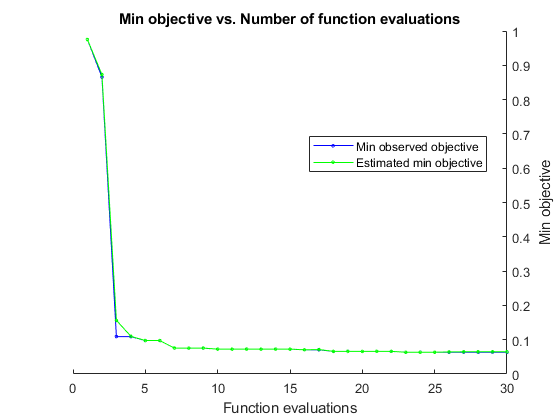

|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Coding | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |       0.975 |      49.101 |       0.975 |       0.975 |     onevsone |      0.35962 |    0.0016077 |
|    2 | Best   |      0.8655 |      5.4628 |      0.8655 |      0.8732 |     onevsall |    0.0036158 |       248.42 |
|    3 | Best   |       0.109 |      20.638 |       0.109 |     0.15646 |     onevsall |       57.804 |      0.19002 |
|    4 | Accept |      0.2905 |      37.189 |       0.109 |     0.10994 |     onevsone |        459.4 |       128.03 |
|    5 | Best   |      0.0975 |      12.018 |   

% Rename variables for clarity:
%   X: Predictor data (rows are observations)
%   Y: Response data
X = x_train_reverb';
Y = y_train_reverb;

% SVM template with gaussian kernel (RBF)
t = templateSVM('KernelFunction','gaussian');

Mdl_reverb = fitcecoc(X,Y,'Coding',"onevsall",'Learners',t, "Prior","uniform", "OptimizeHyperparameters","auto",...
    "HyperparameterOptimizationOptions",struct('AcquisitionFunctionName','expected-improvement-plus'));

## Evaluation

% Compute resubstitution classification error to obtain training error
train_error = resubLoss(Mdl_reverb, 'lossfun', 'classiferror');
disp("Training error: " + train_error*100 + "%");

Training error: 2.25%


% Cross-validate classifier
CVMdl = crossval(Mdl_reverb);
% Compute cross-validation classification error:
cv_error = kfoldLoss(CVMdl, 'lossfun','classiferror');

disp("Validation error: " + cv_error*100 + "%");

Validation error: 6.05%


***Case 1: Low errors***

***    If the validation error is higher than the training error this indicates that there is a case of HIGH VARIANCE***

***    High variance can be solved by adding more training data***

***Case 2: High errors***

***    If both the validation and training error are high this indicates a case of HIGH BIAS***

***    High bias asks for more distinct features***

## Test on augmented noise with other reverberations

***Load in other IR set***

fs = 44100;
IRLen = 40;
dir = "aux_data/IR_Z_fixed/2s/"; % Azimuth
test_acc = zeros(5,1);
names = ["IR44K_2s_10ms";
"IR44K_2s_50ms";
"IR44K_2s_100ms";
"IR44K_2s_500ms";
"IR44K_2s_1000ms"];
for index_IR = 1:5

    IR_reverb = struct2cell(load(dir+names(index_IR)));
    IR_reverb = IR_reverb{1};
    IR_reverb =IR_reverb(:,2);
    IR_reverb = [IR_reverb{:}];
    
    N_tests = 10;
    N_augmentations = N_tests*IRLen;
    
    x_test_reverb = zeros(N_bins,N_augmentations);
    y_test_reverb = zeros(N_augmentations,1);
    
    for k = 1:N_tests
        for i = 1:40
            % Augment noise sample
            if index_noise == 1    % White noise
               noise = randn(fs,1);
               noise = filter(F,noise);
            else                   % Pink noise 
                pink = dsp.ColoredNoise('pink',44100,1);    % Normally distributed white noise
                noise = pink();
                noise = noise/max(noise);
            end
            index = ((k-1)*40) + i;
            noise_aug = conv(noise,IRms(:,i));
            noise_aug = noise_aug(1:fs);
            
            [Pxx, ~] = pmusic(noise_aug,p, nfft);
            
            x_test_reverb(:,index) = normalize(Pxx, 'range');
            y_test_reverb(index) = find(any(i==vec,2),1);
        end
    end
    y_test_reverb = categorical(directions(y_test_reverb));

***Predict test samples***

    y_pred_reverb = predict(Mdl_reverb,x_test_reverb');
    y_pred_reverb(randsample(numel(y_pred_reverb),5));
    %numMisclass = sum(~strcmp(,species(idxVal)));
    test_error_reverb = 1-sum(y_pred_reverb==y_test_reverb)/N_augmentations;
    disp("Test error: " + test_error_reverb*100 + "%");
    test_acc(index_IR) = (1-test_error_reverb)*100;
    disp("Test acc: " + test_acc(index_IR) + "%");
end

Test error: 6.25%


Test acc: 93.75%


Test error: 4.5%


Test acc: 95.5%


Test error: 5.75%


Test acc: 94.25%


Test error: 6%


Test acc: 94%


Test error: 7.5%


Test acc: 92.5%


overall_acc = mean(test_acc);
disp("Overall accuracy: " + overall_acc+"%");

Overall accuracy: 94%
